Generates and saves a centered library of SIM OTF's with different axial lightsheet offsets

%Setup initial parameters:
nphases = 5;
norders = 5;
lattice_period = 1.214; %Lattice period in microns
phase_step = .2428; %Phase step in microns
pxl_dim_PSF = [0.11,0.11,0.1072]  %Voxel dimensions of the PSF in microns

pxl_dim_PSF =     0.1100    0.1100    0.1072


background=105;
PSF_folder = ['V:\Yu\SIM_Alignment_Paper\DemoCode\DemoData\PSF_lib\'];
PSF_file_id = ['PSF'];
PSF_WF_id = ['scan*WF_'];


PSF_lib=dir([PSF_folder,PSF_file_id,'*.tif']);
PSF_WF_lib = dir([PSF_folder,PSF_WF_id,'*.tif']);

numPSF=length(PSF_lib);
centerPSF_index=(1+numPSF)/2;

PSF=loadtiff([PSF_lib(centerPSF_index).folder,'\',PSF_lib(centerPSF_index).name]);

The file was loaded successfully. Elapsed time : 0.943 s.


[nx_PSF,ny_PSF,nimgs_PSF] = size(PSF);
nz_PSF=nimgs_PSF/nphases;


Olib=zeros(nx_PSF,ny_PSF,nz_PSF,norders,numPSF);
%Now load all PSF's in the library and apply the same center correction
for jj=1:numPSF
    jj
    
    %Load the centered PSF data
    wfPSF=loadtiff([PSF_WF_lib(jj).folder,'\',PSF_WF_lib(jj).name]);
    wfPSF=wfPSF-background;
    wfPSF(wfPSF<0)=0;
    [nx_PSF,ny_PSF,nz_PSF] = size(wfPSF);
    
    %First - center the bead in the volume to get rid of any phase ramps in the
    %OTF
    
    %Compute the centroid of the wfPSF by fitting a 3D Gaussian
    
    % generate subregion near the brightest pixel
    [val,ind]=max(abs(wfPSF(:)));
    [I,J,K]=ind2sub([nx_PSF,ny_PSF,nz_PSF],ind);
    wfPSF_subregion=double(abs(wfPSF(I-4:I+4,J-4:J+4,K-4:K+4)));
    
    fitParams=Lsq_Fit_3D_2016_07_19(wfPSF_subregion); 
    fitParams(2:4) = fitParams(2:4)-5;

    shift_vec = [ceil((ny_PSF+1)/2)-J-fitParams(2),ceil((nx_PSF+1)/2)-I-fitParams(3),(ceil((nz_PSF+1)/2)-K-fitParams(4))*(0.2/pxl_dim_PSF(3))];
    
    
    %Load the PSF data and subtract off background
    PSF=loadtiff([PSF_lib(jj).folder,'\',PSF_lib(jj).name]);
    PSF=PSF-background;
    PSF(PSF<0)=0;
    [nx_PSF,ny_PSF,nimgs_PSF] = size(PSF);
    nz_PSF=nimgs_PSF/nphases;


    %Normalize so that the PSF has a unit integrated intensity when summed
    %across all phases
    PSF=double(PSF)./sum(PSF(:));
    
    %Separate the images for each phase and generate the OTFs
    Dr=zeros(nx_PSF,ny_PSF,nz_PSF,nphases);
    Dr_shift=zeros(nx_PSF,ny_PSF,nz_PSF,nphases);
    Dk=zeros(nx_PSF,ny_PSF,nz_PSF,nphases);
    
    for ii=1:nphases
        Dr(:,:,:,ii)=PSF(:,:,ii:5:end);
        %Note - the ceil((nx+1)/2) is there to account for how fftshift and
        %ifftshift deal with even vs. odd sized datasets. Centering the bead at
        %ceil((nx+1)/2)... gives zero phase ramp in the OTF.
        Dr_shift(:,:,:,ii)=ifourierShift3D(Dr(:,:,:,ii),shift_vec);
        Dk(:,:,:,ii)=fftshift(fftn(ifftshift(Dr_shift(:,:,:,ii))));
    end
    
    
    ['Separating information components']
    %Make the forward separation matrix
    [sep_matrix]=make_forward_separation_matrix(nphases,norders,lattice_period,phase_step);
    
    %Make the inverse separation matrix
    inv_sep_matrix=pinv(sep_matrix);
    
    %Separate OTF orders by solving the linear system of equations for each pixel
    O=zeros(nx_PSF,ny_PSF,nz_PSF,norders);
    
    for ii=1:nphases
        ii
        for kk=1:nphases
        O(:,:,:,ii)=O(:,:,:,ii)+inv_sep_matrix(ii,kk)*Dk(:,:,:,kk);
        end
    end
    
    Olib(:,:,:,:,jj)=O;
    save([PSF_lib(jj).folder,'\',PSF_lib(jj).name(1:end-4),'_OTFCentered.mat'],'O')
end

jj = 1

The file was loaded successfully. Elapsed time : 0.336 s.


The file was loaded successfully. Elapsed time : 0.407 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 2

The file was loaded successfully. Elapsed time : 0.238 s.


The file was loaded successfully. Elapsed time : 0.473 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 3

The file was loaded successfully. Elapsed time : 0.331 s.


The file was loaded successfully. Elapsed time : 0.462 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 4

The file was loaded successfully. Elapsed time : 0.361 s.


The file was loaded successfully. Elapsed time : 0.458 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 5

The file was loaded successfully. Elapsed time : 0.332 s.


The file was loaded successfully. Elapsed time : 0.446 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 6

The file was loaded successfully. Elapsed time : 0.362 s.


The file was loaded successfully. Elapsed time : 0.649 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 7

The file was loaded successfully. Elapsed time : 0.331 s.


The file was loaded successfully. Elapsed time : 1.281 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 8

The file was loaded successfully. Elapsed time : 0.357 s.


The file was loaded successfully. Elapsed time : 0.498 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 9

The file was loaded successfully. Elapsed time : 0.494 s.


The file was loaded successfully. Elapsed time : 0.452 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 10

The file was loaded successfully. Elapsed time : 0.336 s.


The file was loaded successfully. Elapsed time : 0.413 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 11

The file was loaded successfully. Elapsed time : 0.332 s.


The file was loaded successfully. Elapsed time : 0.519 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 12

The file was loaded successfully. Elapsed time : 0.735 s.


The file was loaded successfully. Elapsed time : 0.525 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 13

The file was loaded successfully. Elapsed time : 0.925 s.


The file was loaded successfully. Elapsed time : 0.658 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 14

The file was loaded successfully. Elapsed time : 0.607 s.


The file was loaded successfully. Elapsed time : 0.504 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 15

The file was loaded successfully. Elapsed time : 0.532 s.


The file was loaded successfully. Elapsed time : 0.645 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 16

The file was loaded successfully. Elapsed time : 1.011 s.


The file was loaded successfully. Elapsed time : 1.184 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 17

The file was loaded successfully. Elapsed time : 0.483 s.


The file was loaded successfully. Elapsed time : 0.549 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 18

The file was loaded successfully. Elapsed time : 0.776 s.


The file was loaded successfully. Elapsed time : 0.554 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 19

The file was loaded successfully. Elapsed time : 0.664 s.


The file was loaded successfully. Elapsed time : 0.521 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 20

The file was loaded successfully. Elapsed time : 0.804 s.


The file was loaded successfully. Elapsed time : 1.216 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 21

The file was loaded successfully. Elapsed time : 0.540 s.


The file was loaded successfully. Elapsed time : 0.509 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 22

The file was loaded successfully. Elapsed time : 0.399 s.


The file was loaded successfully. Elapsed time : 0.628 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 23

The file was loaded successfully. Elapsed time : 0.491 s.


The file was loaded successfully. Elapsed time : 1.904 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 24

The file was loaded successfully. Elapsed time : 0.427 s.


The file was loaded successfully. Elapsed time : 0.518 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 25

The file was loaded successfully. Elapsed time : 0.557 s.


The file was loaded successfully. Elapsed time : 0.542 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 26

The file was loaded successfully. Elapsed time : 0.689 s.


The file was loaded successfully. Elapsed time : 0.422 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 27

The file was loaded successfully. Elapsed time : 0.683 s.


The file was loaded successfully. Elapsed time : 1.276 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 28

The file was loaded successfully. Elapsed time : 0.628 s.


The file was loaded successfully. Elapsed time : 0.494 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 29

The file was loaded successfully. Elapsed time : 0.531 s.


The file was loaded successfully. Elapsed time : 0.535 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 30

The file was loaded successfully. Elapsed time : 0.357 s.


The file was loaded successfully. Elapsed time : 0.661 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 31

The file was loaded successfully. Elapsed time : 0.376 s.


The file was loaded successfully. Elapsed time : 0.342 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 32

The file was loaded successfully. Elapsed time : 0.391 s.


The file was loaded successfully. Elapsed time : 1.144 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 33

The file was loaded successfully. Elapsed time : 0.406 s.


The file was loaded successfully. Elapsed time : 0.523 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 34

The file was loaded successfully. Elapsed time : 0.630 s.


The file was loaded successfully. Elapsed time : 0.462 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 35

The file was loaded successfully. Elapsed time : 0.680 s.


The file was loaded successfully. Elapsed time : 0.516 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 36

The file was loaded successfully. Elapsed time : 0.615 s.


The file was loaded successfully. Elapsed time : 0.580 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 37

The file was loaded successfully. Elapsed time : 0.903 s.


The file was loaded successfully. Elapsed time : 1.216 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 38

The file was loaded successfully. Elapsed time : 0.578 s.


The file was loaded successfully. Elapsed time : 0.490 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 39

The file was loaded successfully. Elapsed time : 0.328 s.


The file was loaded successfully. Elapsed time : 0.510 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 40

The file was loaded successfully. Elapsed time : 0.616 s.


The file was loaded successfully. Elapsed time : 0.401 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 41

The file was loaded successfully. Elapsed time : 0.458 s.


The file was loaded successfully. Elapsed time : 0.532 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 42

The file was loaded successfully. Elapsed time : 0.572 s.


The file was loaded successfully. Elapsed time : 0.790 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 43

The file was loaded successfully. Elapsed time : 0.751 s.


The file was loaded successfully. Elapsed time : 0.642 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 44

The file was loaded successfully. Elapsed time : 0.620 s.


The file was loaded successfully. Elapsed time : 0.750 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 45

The file was loaded successfully. Elapsed time : 0.673 s.


The file was loaded successfully. Elapsed time : 0.483 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 46

The file was loaded successfully. Elapsed time : 0.945 s.


The file was loaded successfully. Elapsed time : 1.294 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 47

The file was loaded successfully. Elapsed time : 0.687 s.


The file was loaded successfully. Elapsed time : 0.597 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 48

The file was loaded successfully. Elapsed time : 0.654 s.


The file was loaded successfully. Elapsed time : 0.424 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 49

The file was loaded successfully. Elapsed time : 0.463 s.


The file was loaded successfully. Elapsed time : 0.439 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 50

The file was loaded successfully. Elapsed time : 0.464 s.


The file was loaded successfully. Elapsed time : 0.964 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

jj = 51

The file was loaded successfully. Elapsed time : 0.703 s.


The file was loaded successfully. Elapsed time : 0.901 s.


ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

ii = 4

ii = 5

save([PSF_lib(jj).folder,'\OTF_library.mat'],'Olib');

figure
n_PSF = 25

n_PSF = 25

phase = 3

phase = 3

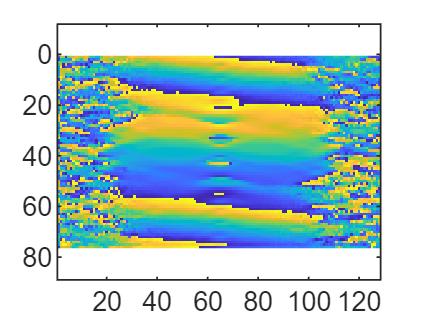

imagesc(imrotate(squeeze(angle(Olib(:,ny_PSF/2,:,phase,n_PSF))),90));
axis equal
caxis([-pi pi])

figure
n_PSF = 29

n_PSF = 29

phase = 3

phase = 3

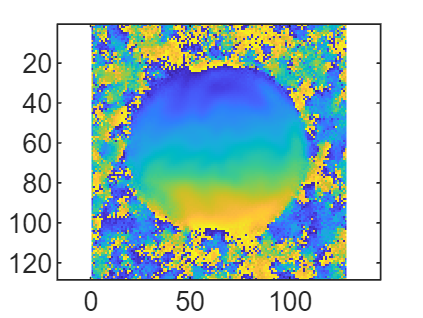

imagesc(imrotate(squeeze(angle(Olib(:,:,nz_PSF/2,phase,n_PSF))),90));
axis equal
caxis([-pi pi])